# 中山大学电子与通信工程学院

# 《数字信号处理实验》实验报告

## 实验三 离散系统中的卷积与z变换

## 一、实验目的

- 通过实验进一步了解卷积定理，了解卷积的过程

- 掌握应用线性卷积求解离散时间系统相应的基本方法

- 加深对离散LSI系统时域特性的认识

- 掌握MATLAB求解离散时间系统响应的基本方法

- 加深对离散系统变换域分析——z变换的理解

- 掌握进行z变换和z反变换的基本方法，了解部分分式法在z反变换中的应用

## 二、实验要求

- 每个实验内容都要清晰展示实验过程和实验结果。

- 绘图时必须明确标出各个坐标轴的意义和单位。

- 绘制多个子图时要明确标出各个子图所画的内容。

- 绘制多个信号时采用不同的线型和颜色区分、添加图例。

- 严禁抄袭、复制，发现雷同报告或代码双方成绩均作废！！

## 三、实验原理

（根据具体实验内容和要求，简述所涉及的数字信号处理基本概念、理论知识和实验原理，对基本概念和理论进行解释、列出必要的公式）

- 卷积的本质即先将一个函数或序列反转，然后与另一个函数或序列滑动叠加，卷积的物理含义为，输入信号经过线性系统的输出信号即为输入信号和系统响应函数的卷积。

- 卷积定理是傅立叶变换满足的一个重要性质。卷积定理指出，函数卷积的傅立叶变换是函数傅立叶变换的乘积。具体分为时域卷积定理和频域卷积定理，时域卷积定理即时域内的卷积对应频域内的乘积；频域卷积定理即频域内的卷积对应时域内的乘积，两者具有对偶关系。

- 给定系统差分方程和输入，有三种方法可以求出输出相应。分别为递推法、卷积法、频域相乘法。其中频域相乘法原理为时域的卷积等效为频域的相乘，在Matlab中常用filter求解系统响应，impz求解单位脉冲响应，dstep求解单位阶跃响应。

- LSI系统为线性时不变系统，该系统的输出响应可表示为输入函数和输出函数的卷积。其中线性系统满足叠加性和齐次性，所谓叠加性是指当几个输入信号共同作用于系统时，总的输出等于每个输入单独作用时产生的输出之和；齐次性是指当输入信号增大若干倍时，输出也相应增大同样的倍数。时不变系统为输出相应不随输入相应加在系统上的时间变化而变化。

- Z变换（Z-transformation）是对离散序列进行的一种数学变换，常用于求线线性时不变差分方程的解。逆Z变换时将Z变换后的数学数学函数转换为原离散序列。

- 响应分为完全响应、零状态响应、零输入相应。其中零状态相应为系统初始状态下有外在输入的响应，零输入相应为没有外在输入的情况下仅有系统初始状态引起的响应，完全响应为零状态响应与零输入响应的和。在Matlab中可用dlsim函数求解数字系统的零状态响应，用filter函数求解零输入相应或者完全响应。

## 四、实验所用MATLAB函数

- filtic函数：xi=filtic(b,a,x0)    输入系统初始状态，输出等效的初始条件，为filter函数提供等效的初始条件。b和a分别为离散LTI系统的系统函数的H(z)的分子和分母多项式系数。

- filter函数：y=filter(b,a,x,xi)    对数字系统的输入信号进行滤波处理，其中x为系统输入，xi为系统等效的初始条件，一般由filtic函数生成，y为系统的相应输出。b和a分别为离散LTI系统的系统函数的H(z)的分子和分母多项式系数。

- dlsim函数：y=dlsim(b,a,x)    求解数字系统的零状态相应，当x为输入信号，y为零状态响应，b和a分别为离散LTI系统的系统函数的H(z)的分子和分母多项式系数。

- syms函数：用于创建符号对象。

- ztrans函数：F=ztrans(f)    求解序列的z变换。其中f的以n为独立自变量(符号对象)的Z变换F。

- conv函数：在离散时间的情况下，系统对任意输入信号x(k)的零状态响应y(k)=x(k)*h(k)。MATLAB的conv函数可以帮我们快速求解出两个离散序列的卷积。也可以用作求多项式乘积的系数。

- repmat函数：复制扩展矩阵。

- residuez函数：[r,p,k]=residuez(b,a)    将离散时间系统转换为部分分数扩展或留数形式。其中r为留数，p为极点，k为直接项。

- impz函数：求解数字系统的冲激响应。

## 五、实验内容、方法、代码与结果

### **题目1**：编写MATLAB程序，已知一个系统的差分方程为y(n)=0.7y(n-1)+2x(n)-x(n-2)，试求此系统的输入序列x(n)=u(n-3)的响

### 应。

**解答1**：

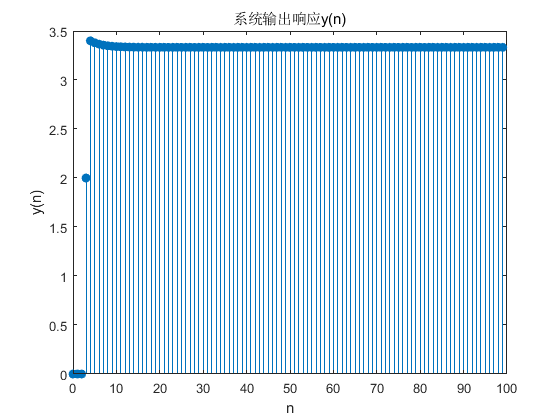

clc;
clear;
b=[2 0 -1];
a=[1 -0.7];
n=0:100-1;
x=n>=3;
y=filter(b,a,x);
figure();
stem(n,y,'filled');
xlabel('n');
ylabel('y(n)');
title('系统输出响应y(n)');

### **题目2**：编写MATLAB程序，已知一个LSI系统的差分方程表示式为y(n)-0.5y(n-1)+y(n-6)-0.5y(n-7)=x(n)-x(n-1)+x(n-2)，满足初

### 始条件y(-1)=0，x(-1)=0，试用dlsim和filter两种方法求此系统的输入序列x(n)为下列信号时的响应。

### 1.$\mathbf{x}(\mathbf{n})=\mathbf{u}(\mathbf{n}-3)$

### 2.$\mathbf{x}(\mathbf{n})=\delta (\mathbf{n})-\delta (\mathbf{n}-5)$

### 3.$\mathbf{x}(\mathbf{n})=e^{0\ldotp 1\mathbf{n}} \mathbf{u}(\mathbf{n}-3)$

**解答2**：

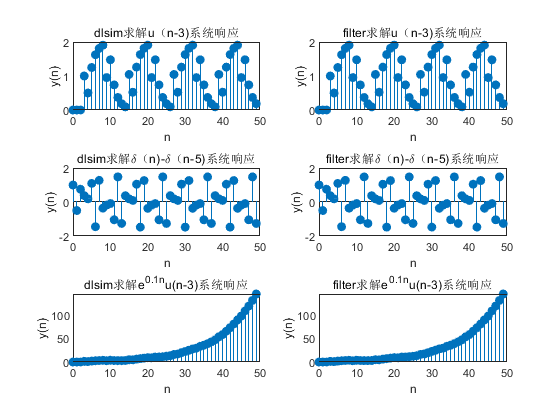

clc;
clear;
n=0:50-1;
b=[1 -1 1 0 0 0 0 0];
a=[1 -0.5 0 0 0 0 1 -0.5];

figure();
subplot(3,2,1);
x1=n>=3;
y11=dlsim(b,a,x1);
stem(n,y11,'filled');
xlabel('n');
ylabel('y(n)');
title('dlsim求解u（n-3)系统响应');
subplot(3,2,2);
x0=0;
y0=0;
xi1=filtic(b,a,x0,y0);
y12=filter(b,a,x1,xi1);
stem(n,y12,'filled');
xlabel('n');
ylabel('y(n)');
title('filter求解u（n-3)系统响应');

subplot(3,2,3);
x2=n==0|n==5;
y21=dlsim(b,a,x2);
stem(n,y21,'filled');
xlabel('n');
ylabel('y(n)');
title('dlsim求解\delta（n)-\delta（n-5)系统响应');
subplot(3,2,4);
x0=0;
y0=0;
xi2=filtic(b,a,x0,y0);
y22=filter(b,a,x2,xi2);
stem(n,y22,'filled');
xlabel('n');
ylabel('y(n)');
title('filter求解\delta（n)-\delta（n-5)系统响应');

subplot(3,2,5);
x3=exp(0.1*n).*(n>=3);
y31=dlsim(b,a,x3);
stem(n,y31,'filled');
xlabel('n');
ylabel('y(n)');
title('dlsim求解e^{0.1n}u(n-3)系统响应');
subplot(3,2,6);
x0=0;
y0=0;
xi3=filtic(b,a,x0,y0);
y32=filter(b,a,x3,xi3);
stem(n,y32,'filled');
xlabel('n');
ylabel('y(n)');
title('filter求解e^{0.1n}u(n-3)系统响应');

### **题目3**：一个LSI系统的系统函数表示式为：

### 
$$H(z)=\frac{0\ldotp 187632+0\ldotp 241242z^{-1} +0\ldotp 241242z^{-2} +0\ldotp 187632z^{-3} }{1-0\ldotp 602012z^{-1} +0\ldotp 495684z^{-2} -0\ldotp 035924z^{-3} }$$


### 满足初始条件：y(-1)=5，y(-2)=5，试用filtic和filter子函数求此系统的输入序列为下列信号时的零输入、零状态及完全响应。

### 1.$\mathbf{x}(\mathbf{n})=\delta (\mathbf{n}-3)$

### 2.$\mathbf{x}(\mathbf{n})={\mathbf{R}}_5 (\mathbf{n})$

### 3.$\mathbf{x}(\mathbf{n})=\cos \frac{2\pi }{3}\mathbf{n}+\sin \frac{3\pi }{10}\mathbf{n}$

**解答3**：

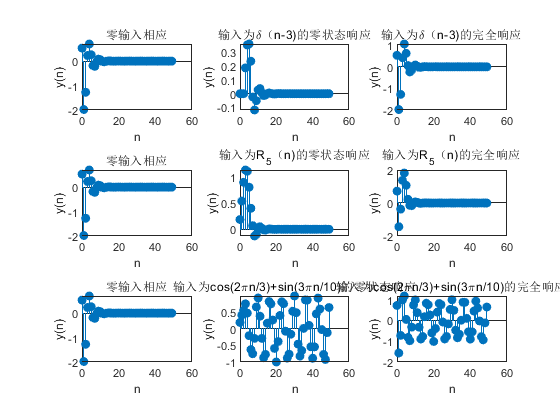

clc;
clear;
N=50;
n=0:N-1;
x0=zeros(1,N);
a=[1 -0.602012 0.495684 -0.035924];
b=[0.187632 0.241242 0.241242 0.187632];
y0=[5 5];
xi=filtic(b,a,y0);
x1=n==3;
y1_zi=filter(b,a,x0,xi);
y1_zs=filter(b,a,x1);
y1=filter(b,a,x1,xi);
figure();
subplot(3,3,1);
stem(n,y1_zi,'filled');
xlabel('n');
ylabel('y(n)');
title('零输入相应');
subplot(3,3,2);
stem(n,y1_zs,'filled');
xlabel('n');
ylabel('y(n)');
title('输入为\delta（n-3)的零状态响应');
subplot(3,3,3);
stem(n,y1,'filled');
xlabel('n');
ylabel('y(n)');
title('输入为\delta（n-3)的完全响应');

x2=[ones(1,5),zeros(1,45)];
y2_zi=filter(b,a,x0,xi);
y2_zs=filter(b,a,x2);
y2=filter(b,a,x2,xi);
subplot(3,3,4);
stem(n,y2_zi,'filled');
xlabel('n');
ylabel('y(n)');
title('零输入相应');
subplot(3,3,5);
stem(n,y2_zs,'filled');
xlabel('n');
ylabel('y(n)');
title('输入为R_{5}（n)的零状态响应');
subplot(3,3,6);
stem(n,y2,'filled');
xlabel('n');
ylabel('y(n)');
title('输入为R_{5}（n)的完全响应');

x3=cos(2*pi*n/3)+sin(3*pi*n/10);
y3_zi=filter(b,a,x0,xi);
y3_zs=filter(b,a,x3);
y3=filter(b,a,x3,xi);
subplot(3,3,7);
stem(n,y3_zi,'filled');
xlabel('n');
ylabel('y(n)');
title('零输入相应');
subplot(3,3,8);
stem(n,y3_zs,'filled');
xlabel('n');
ylabel('y(n)');
title('输入为cos(2\pin/3)+sin(3\pin/10)的零状态响应');
subplot(3,3,9);
stem(n,y3,'filled');
xlabel('n');
ylabel('y(n)');
title('输入为cos(2\pin/3)+sin(3\pin/10)的完全响应');

### **题目4**：编写MATLAB程序，求以下各序列的z变换。

### 1.${\mathbf{x}}_1 \left(\mathbf{n}\right)=\mathbf{n}{\mathbf{a}}^{\mathbf{n}}$

### 2.${\mathbf{x}}_4 \left(\mathbf{n}\right)={\mathbf{e}}^{-\mathbf{a}\mathbf{n}} \mathbf{s}\mathbf{i}\mathbf{n}\left(\mathbf{n}\omega_0 \right)$

**解答4**：

clc;
clear;
syms n a w0

x1=n*a^n;
XZ1=ztrans(x1)

$$XZ1 = \frac{a\,z}{{\left(a-z\right)}^{2}}$$


x2=exp(-a*n)*sin(n*w0);
XZ2=ztrans(x2)

$$XZ2 = \frac{z\,{\mathrm{e}}^{a}\,\sin\left(w_{0}\right)}{{\mathrm{e}}^{2\,a}\,z^{2}-2\,{\mathrm{e}}^{a}\,\cos\left(w_{0}\right)\,z+1}$$

### **题目5**：用编写MATLAB程序，用部分分式法求解下列系统的z反变换，写出x(n)的表示式，并用图形与impz求得的结果相比较，

### 取前10个点作图。

### 1.$\mathbf{X}\left(\mathbf{z}\right)=\frac{10+20{\mathbf{z}}^{-1} }{1+8{\mathbf{z}}^{-1} +19{\mathbf{z}}^{-2} +12{\mathbf{z}}^{-3} }$

### 2.$\mathbf{X}\left(\mathbf{z}\right)=\frac{1}{{(1-0\ldotp 9{\mathbf{z}}^{-1} )}^2 (1+0\ldotp 9{\mathbf{z}}^{-1} )}$

**解答5**：

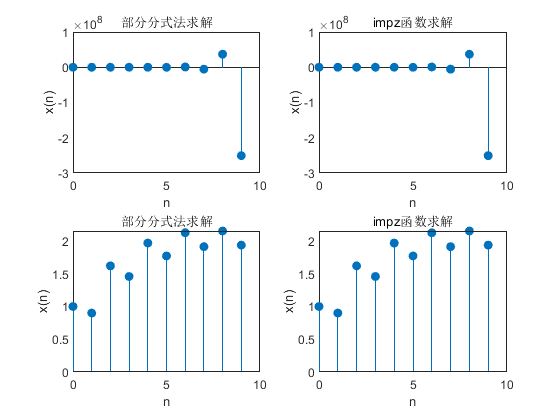

clc;
clear;
N=10;
n=0:N-1;
b1=[10 20 0 0];
a1=[1 8 10 12];
[r,p,~]=residuez(b1,a1);
x1_re=repmat(r,1,N).*(repmat(p,1,N).^repmat(n,3,1));
x1_re=sum(x1_re);
figure();
subplot(2,2,1);
stem(n,x1_re,'filled');
xlabel('n');
ylabel('x(n)');
title('部分分式法求解');
subplot(2,2,2);
x1_im=impz(b1,a1,N);
stem(n,x1_im,'filled');
xlabel('n');
ylabel('x(n)');
title('impz函数求解');

b2=1;
a2=conv(conv([1 -0.9],[1 -0.9]),[1 0.9]);
[r,p,~]=residuez(b2,a2);
x2_re=r(1)*p(1).^n+r(2)*p(2).^n+r(3)*p(3).^n.*(n+1);
subplot(2,2,3);
stem(n,abs(x2_re),'filled');
xlabel('n');
ylabel('x(n)');
title('部分分式法求解');
subplot(2,2,4);
x2_im=impz(b2,a2,N);
stem(n,x2_im,'filled');
xlabel('n');
ylabel('x(n)');
title('impz函数求解');